#                        Blind Source Separation

##                                            HW9-Section-2

                 Mohammadreza Arani         :::::::::::::         810100511

                                                           1402/03/14   

clear; clc; close all;

Data_hw9 = load("hw9.mat");

A = Data_hw9.A;
S = Data_hw9.S;
Noise = Data_hw9.Noise;

X = A*S+Noise;

## Step-1: Whitening:

[U , Gamma] = eig(X*X');
W = Gamma^(-0.5);
Z = W*U'*X; % Whitened Data

R_z = Z*Z';
disp(R_z);

    1.0000    0.0000   -0.0000
    0.0000    1.0000    0.0000
   -0.0000    0.0000    1.0000



## Step-2: Perform ALternation Minimization for each column of B!

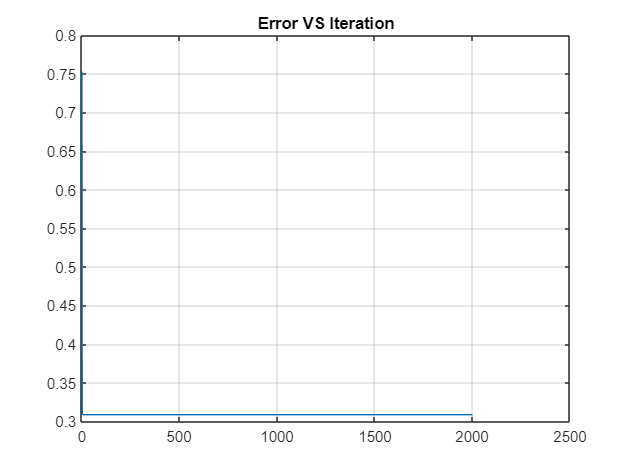


B = generate_orthonormal_matrix(size(A,1))  ; % Because B and A are in the same size due to the fact that we have M=N!



mu       = 1e+02;
Max_Iter = 2e+3;
thresh_cntr = 1e-1;
thresh_B = 1e-8;

Error_Iter_deflate_EQ = zeros(1,Max_Iter)+inf;
cntr = 1;

y_hat = B*Z;
MIN_ERR = inf;
while(true)
    B_prev = B;
    
    % Update B:
    for i=1:length(B) % Each Row
         % Estimation of Score Function:
         [Theta_hat , Score_Func_y ] = Theta_Calc_Kernel(y_hat(i,:));
         StepSize = ( Score_Func_y*Z' )/length(Z) ;
        %  StepSize = normalize(StepSize,2,"norm");
         B(i,:)        =  B(i,:) - mu*StepSize*(B(i,:)'*B(i,:))  ; % New Update Rule for Equivariant!
         B(i,:)        =  B(i,:)/norm(B(i,:));   % Normalization
         B(i,:)        =  ( eye(size(B)) - B(1:i-1,:)'*B(1:i-1,:)   )* B(i,:)';  % Orthogonality
         
    end
    
    [Error_Perm,y_Hat_Chosen,B] = Perm_AMP_Disamb(B,S,Z);
    Error_Iter_deflate_EQ(cntr)     = min(Error_Perm);  
    y_hat = B*Z;
%     Errors_ICA = norm(y-S)/norm(S);
%     Error_Iter_deflate(p) = min(Errors_ICA);




    % Check Convergence:
    if( (abs(Error_Iter_deflate_EQ(1,cntr))<thresh_cntr) || (cntr>Max_Iter) ) %|| ( norm(B_prev - B,'fro')<thresh_B  ) 
        break;
    end
    if ( Error_Iter_deflate_EQ(cntr)<MIN_ERR  )
        y_hat_best = y_Hat_Chosen;
        B_hat_best = B;
        Index_Best = cntr;
        MIN_ERR = Error_Iter_deflate_EQ(cntr);
    end
    cntr = cntr +1;

end

figure()
plot(Error_Iter_deflate_EQ)
grid on
title("Error VS Iteration")

## Results:

disp("calculated Error Equals to: "+min(Error_Iter_deflate_EQ))

calculated Error Equals to: 0.30849


disp(abs(B*W*U'*A))

    0.9895    0.0259    0.0689
    0.0204    1.0942    0.2385
    0.0440    0.3701    1.1142



## Signal Illustration:

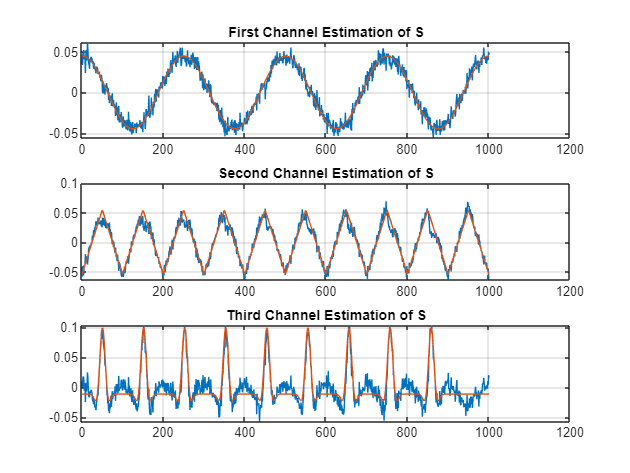

% Recovered S_hat:
y = y_Hat_Chosen;


figure()
subplot(3,1,1)
plot(y(1,:))% Permutaion
hold on
plot(S(1,:))
hold off
grid on
title("First Channel Estimation of S")


subplot(3,1,2)
plot(y(2,:))
hold on
plot(S(2,:))
hold off
grid on
title("Second Channel Estimation of S")


subplot(3,1,3)
plot(y(3,:))
hold on
plot(S(3,:))
hold off
grid on
title("Third Channel Estimation of S")

## Functions:

function matrix = generate_orthonormal_matrix(size)
    % Step 1: Generate a random matrix
    matrix = randn(size, size);
    
    % Step 2: Apply the Gram-Schmidt process
    for i = 1:size
        for j = 1:i-1
            matrix(:, i) = matrix(:, i) - dot(matrix(:, j), matrix(:, i)) * matrix(:, j);
        end
    end
    
    % Step 3: Normalize each column
    norms = vecnorm(matrix);
    matrix = matrix ./ norms;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [Theta_hat, PSI_hat] = Theta_Calc_Kernel(y)
% Theta Hat Calculation Function for Kernel Method+MSE:

Coeff = [0,1,2,3,4,5];
N = length(Coeff);
Num_of_Channels = size(y(:,1));

Theta_hat        = zeros(Num_of_Channels(1,1),N);
PSI_hat = zeros(size(y));


    for n=1:Num_of_Channels(1,1)
        y_temp = y(n,:);
        ky = [ones(size(y_temp)) ; y_temp; y_temp.^2; y_temp.^3; y_temp.^4; y_temp.^5   ];
        ky_prime = [zeros(size(y_temp))  ; ones(size(y_temp)); 2*y_temp; 3*y_temp.^2; 4*y_temp.^3; 5*y_temp.^4];
    
        Theta_hat(n,:) = pinv(ky*ky')/length(y_temp)*mean(ky_prime,2); 
        PSI_hat(n,:)   = Theta_hat(n,:)*ky;
    end

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [Error_Perm,S_Hat_Chosen,B]  = Perm_AMP_Disamb(B,S,Z) %% Perm_AMP_Disamb

    Final_Result_S_hat = calculate_permutations_and_Signs(B);
    % Calc the Error:
    L3 = size(Final_Result_S_hat,3);
    Error_Perm = zeros(1,L3);
    for i=1:L3
        S_hat_temp =  Final_Result_S_hat(:,:,i)*Z;
        Error_Perm(1,i) = norm(S_hat_temp-S,"fro")/norm(S,"fro"); 
    end
    [~ , idx ] = min(Error_Perm);
    S_Hat_Chosen = Final_Result_S_hat(:,:,idx)*Z;
    B = Final_Result_S_hat(:,:,idx);
end

function    Final_Result = calculate_permutations_and_Signs(matrix)    
    num_of_columns_matrix = size(matrix,2);
    variations = calculate_variations(matrix);
    cntr =1;
    %Temp = zeros(size(variations(:,:,1)));
    Final_Result = zeros([size(matrix),  (2^num_of_columns_matrix)*factorial(num_of_columns_matrix) ]);
    for j=1:size(variations,3)
        Temp = variations(:,:,j);

         num_of_columns = size(Temp,2);
         Different_Col_Arranges = perms(1:num_of_columns);
        for i=1:size(Different_Col_Arranges,1)
            Final_Result(:,:,cntr) =  Temp(:,Different_Col_Arranges(i,:))  ;
            cntr = cntr +1; 
        end
    end


end


function variations = calculate_variations(matrix)
    % Get the size of the matrix
    [num_rows, num_cols] = size(matrix);
    
    % Generate all possible combinations of signs
    sign_combinations = cell(1, num_rows);
    [sign_combinations{:}] = ndgrid([-1, 1]);
    sign_combinations = cellfun(@(x) x(:), sign_combinations, 'UniformOutput', false);
    sign_combinations = cat(2, sign_combinations{:});
    
    % Calculate the number of variations
    num_variations = size(sign_combinations, 1);
    
    % Initialize the variations array
    variations = zeros(num_rows, num_cols, num_variations);
    
    % Generate the variations
    for i = 1:num_variations
        % Apply the sign variations to each row
        variations( :, :, i) = matrix .* reshape(sign_combinations(i, :), 1, num_rows, 1);
    end
end
